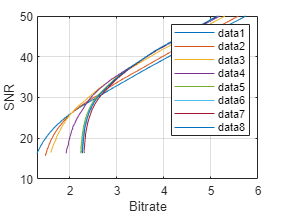

clear
[file,fs] = audioread("hey04_8bit.wav");
%[file,fs] = audioread("nuit04_8bit.wav");

x = file;
sigma2 = mean(x.^2);


n = 30;
snr_arr = zeros(n,1);
btr_arr = zeros(n,1);
p_size = 8;

for o = 1:p_size
for k = 1:n
delta = 0.003 + 0.005*(k-1);

 [xhat, q, p, d, dhat] = pred_coder(x, delta, o);

%huffman
% file_prob = zeros(size(q,1),1);
% for i = 2:size(q,1)
%     file_prob(i,1) = q(i,1) - q(i-1,1);
% end
file_prob = q - min(q)+1;

h = random_distribution(file_prob);
l = huffman(h);

D = mean((x-xhat).^2);

SNR = 10*log10(sigma2/D);

snr_arr(k) = SNR;
btr_arr(k) = l;
end
plot(btr_arr, snr_arr)
hold on
grid on
legend
xlabel('Bitrate');
ylabel('SNR');
end

hold off